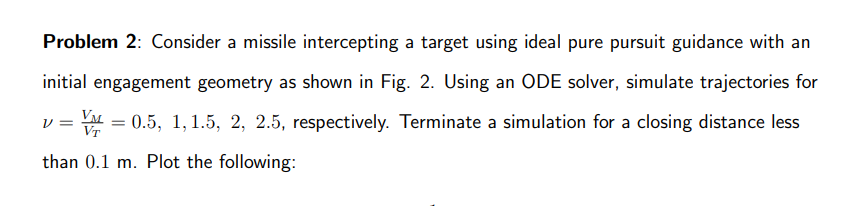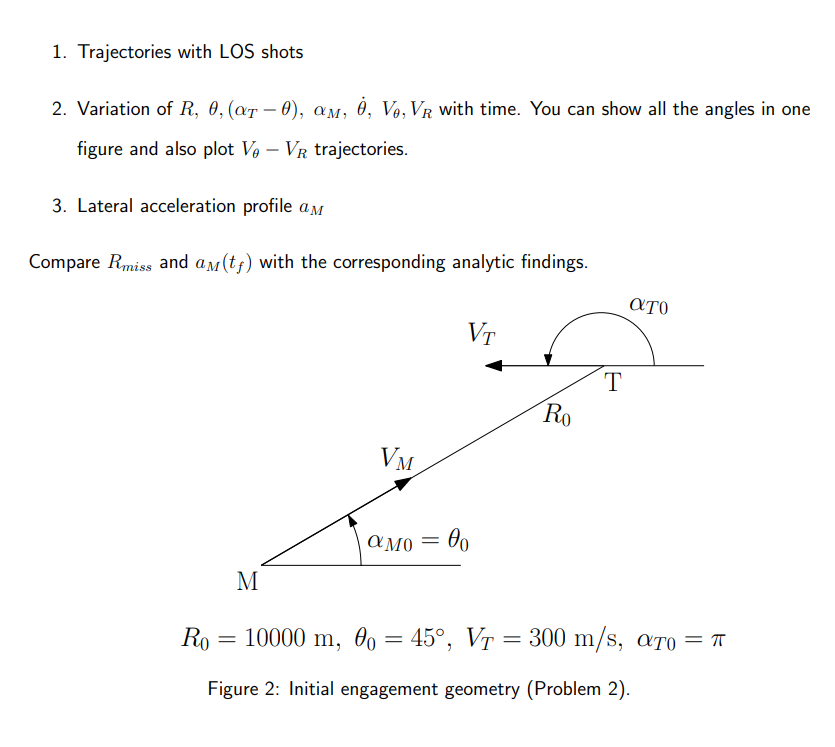

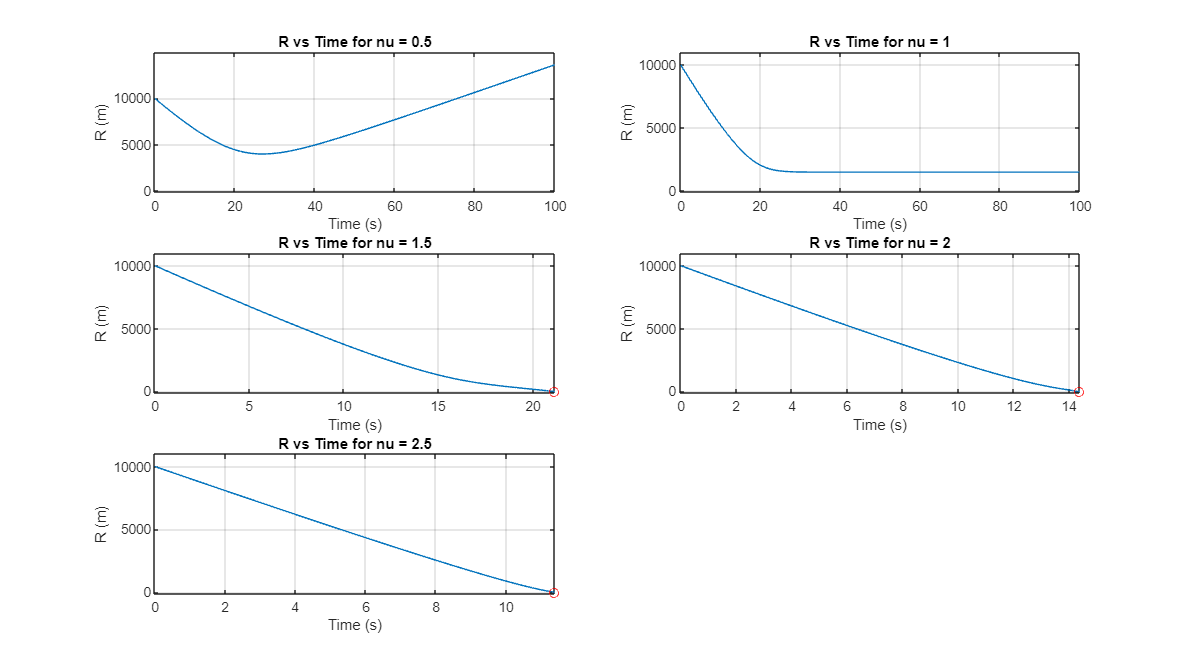

clc;
clear all;
VT = 300;
alphaT0 = pi;
R0 = 10000;
theta0 = 45;
theta0 = deg2rad(theta0);
nu_values = [0.5, 1, 1.5, 2, 2.5];

tspan = [0 100];


t_results = cell(length(nu_values), 1);
R_results = cell(length(nu_values), 1);
theta_results = cell(length(nu_values), 1);
aM_results = cell(length(nu_values), 1);
aM0= zeros(length(nu_values), 1);
theta_dot_results = cell(length(nu_values), 1);

termination_points = zeros(length(nu_values), 2);


for i = 1:length(nu_values)
    nu = nu_values(i);
    %aM0(i,1) = (VT*(VT*nu_values(i))* sin(alphaT0-theta0))/R0;

    %y0 = [R0; theta0; aM0(i)];
    y0 = [R0; theta0];
    options = odeset('Events', @projEvents, 'RelTol', 1e-10, 'AbsTol', 1e-10);
    
    [t,y] = ode45(@(t,y) pure_pursuit_odes(t, y, VT, nu, alphaT0), tspan, y0, options);
    %[t,y] = ode45(@(t,y) pure_pursuit_odes(t, y, VT, nu, alphaT0), tspan, y0);

    t_results{i} = t;
    R_results{i} = y(:,1);
    theta_results{i} = y(:,2);
    %aM_results{i} = y(:,3);

    if ~isempty(t) && y(end, 1) < 0.1
        termination_points(i, :) = [t(end), y(end, 1)];
    end
end

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
for i = 1:length(nu_values)
    subplot(3, 2, i);
    plot(t_results{i}, R_results{i});
    title(['R vs Time for nu = ', num2str(nu_values(i))]);
    xlabel('Time (s)');
    ylabel('R (m)');
    grid on;
    
    axis([0 max(t_results{i}), -100 (max(R_results{i})+0.1*max(R_results{i}))]);
    ytickformat('%g');
    
    if termination_points(i, 1) ~= 0
        hold on;
        plot(termination_points(i, 1), termination_points(i, 2), 'ro');
        hold off;
    end
end

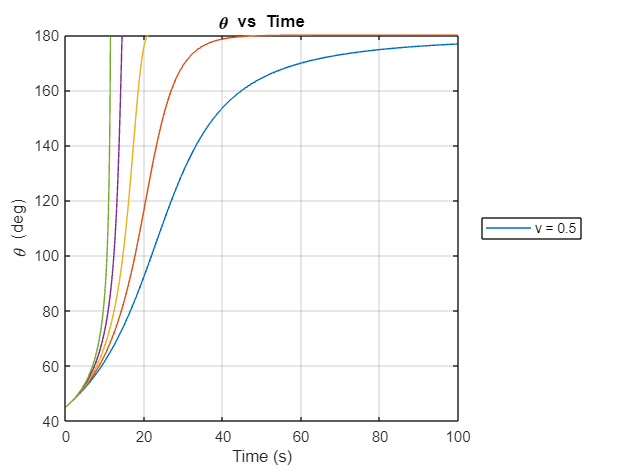

figure;
for i = 1:length(nu_values)
    theta = theta_results{i};
    theta = rad2deg(theta);
    t = t_results{i};
  
    plot(t, theta, 'DisplayName', ['ν = ', num2str(nu_values(i))]);
    hold on;
    title('\theta vs Time');
    xlabel('Time (s)');
    ylabel('\theta (deg)');
    %axis([0  max(tspan), 0 200]);
    legend('Location', 'eastoutside');
    grid on;
end

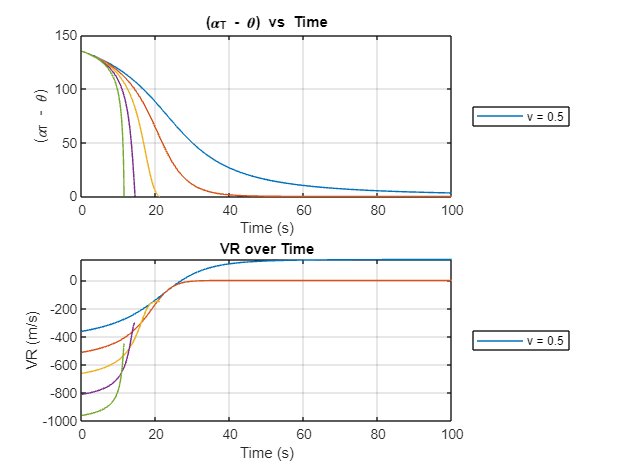

figure;
subplot(2,1, 1);
for i = 1:length(nu_values)
    theta = theta_results{i};
    alphaT_minus_theta = alphaT0 - theta;
    alphaT_minus_theta = rad2deg(alphaT_minus_theta);
    t = t_results{i};    
    plot(t, alphaT_minus_theta, 'DisplayName', ['ν = ', num2str(nu_values(i))]);
    hold on;
    title('(\alpha_T - \theta) vs Time');
    xlabel('Time (s)');
    ylabel('(\alpha_T - \theta)');
    legend('Location', 'eastoutside');
    grid on;    
end

subplot(2,1, 2);
for i = 1:length(nu_values)
    theta = theta_results{i};
    alphaT_minus_theta = alphaT0 - theta;
    VR = VT * cos(alphaT_minus_theta) - nu_values(i) * VT;
    t = t_results{i};
    % VR vs Time
    plot(t, VR, 'DisplayName', ['ν = ', num2str(nu_values(i))]);
    hold on;
    title('VR over Time');
    xlabel('Time (s)');
    ylabel('VR (m/s)');
    legend('Location', 'eastoutside');
    grid on;

end

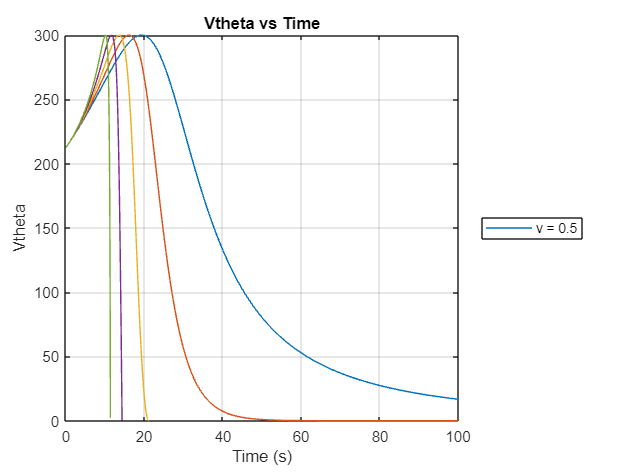

figure;
for i = 1:length(nu_values)
    theta = theta_results{i};
    alphaT_minus_theta = alphaT0 - theta;
    Vtheta = VT * sin(alphaT_minus_theta);
    t = t_results{i};
    plot(t, Vtheta, 'DisplayName', ['ν = ', num2str(nu_values(i))]);
    hold on;
    title('Vtheta vs Time');
    xlabel('Time (s)');
    ylabel('Vtheta');
    legend('Location', 'eastoutside');
    grid on;

end

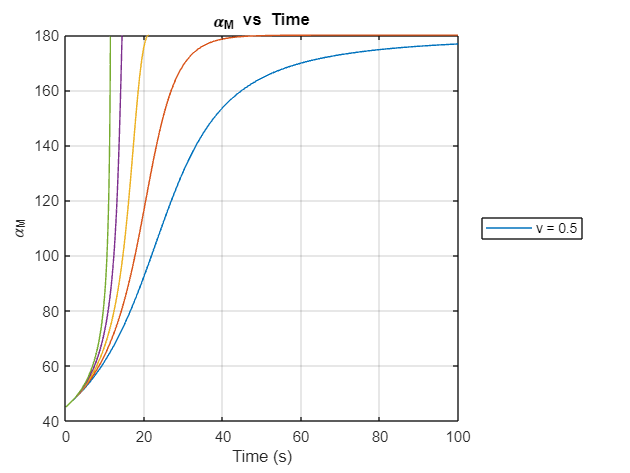

% Calculate and plot additional parameters
figure;

for i = 1:length(nu_values)
    t = t_results{i};
    % R = R_results{i};
    theta = theta_results{i};
    %alphaT_minus_theta = alphaT0 - theta;
    alphaM = theta;
    % theta_dot = [diff(theta)./diff(t); 0]; 
    % Vtheta = (VT./R) .* sin(alphaT_minus_theta);
    % VR = VT * cos(alphaT_minus_theta) - nu_values(i) * VT;    
    plot(t, rad2deg(alphaM), 'DisplayName', ['ν = ', num2str(nu_values(i))]);
    hold on;
    title('\alpha_M vs Time');
    xlabel('Time (s)');
    ylabel('\alpha_M');
    legend('Location', 'eastoutside');
    grid on;
    
    % alpha_m_dot(:,i) = gradient(alphaM(:,i),t);
    % alpha_m_dot0 = alpha_m_dot(1,i);
end

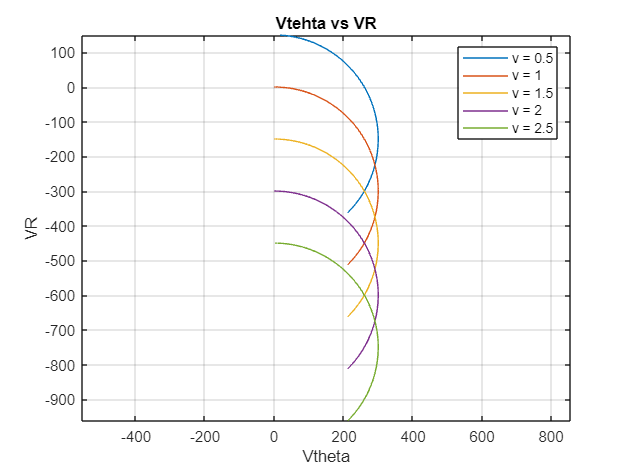

figure;

for i = 1:length(nu_values)
    theta = theta_results{i};
    R = R_results{i};
    alphaT_minus_theta = alphaT0 - theta;
    Vtheta = VT * sin(alphaT_minus_theta);
    VR = VT * cos(alphaT_minus_theta) - nu_values(i) * VT;
    
    plot(Vtheta, VR, 'DisplayName', ['ν = ', num2str(nu_values(i))]);
    hold on;
    title('Vtehta vs VR');
    xlabel('Vtheta');
    ylabel('VR');
    legend('-DynamicLegend');
    axis('equal')
    grid on;
end

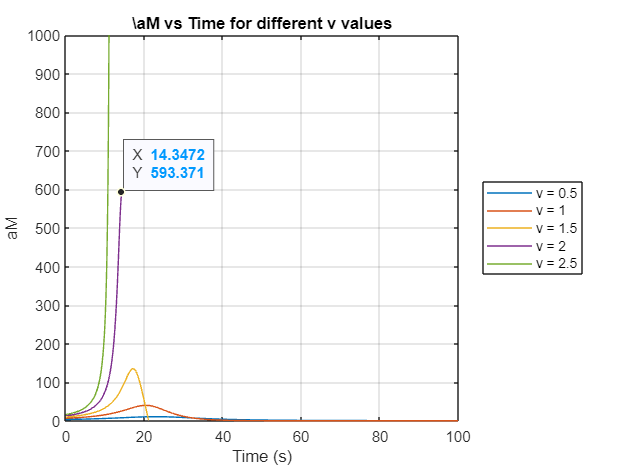

% 
% figure;
% hold on;
% for i = 1:length(nu_values)
%     t = t_results{i};
%     aM = aM_results{i};
%     plot(t, aM, 'DisplayName', ['ν = ', num2str(nu_values(i))]);
% end
% title('aM vs Time');
% xlabel('Time (s)');
% ylabel('Lateral Acceleration (m/s^2)');
% legend('Location', 'eastoutside');
% grid on;
% hold off;
figure;
for i = 1:length(nu_values)
    t = t_results{i};
    theta = theta_results{i};
   
    theta_dot = gradient(theta, t);
    theta_dot_results{i} = theta_dot;

    t = t_results{i};
    aM_results  = nu_values(i) * VT * theta_dot_results{i};
    
    plot(t, aM_results, 'DisplayName', ['ν = ', num2str(nu_values(i))]);
    hold on;
    
    title('\aM vs Time for different ν values');
    xlabel('Time (s)');
    ylabel('aM');
    legend show;
    legend('Location', 'eastoutside');
    grid on;
    ytickformat('%g');
    axis([0 max(tspan), 0 1e3]);
    
end

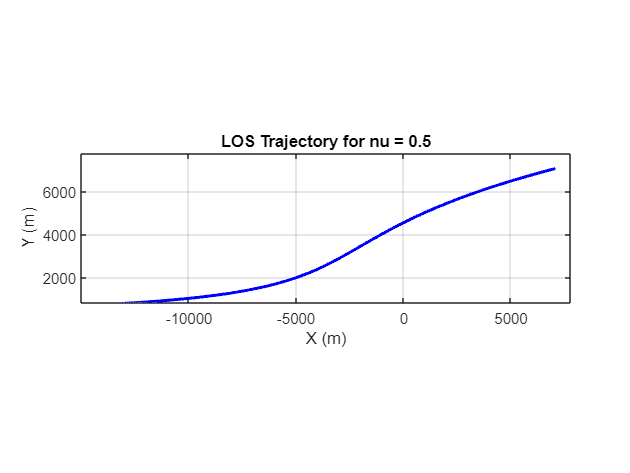

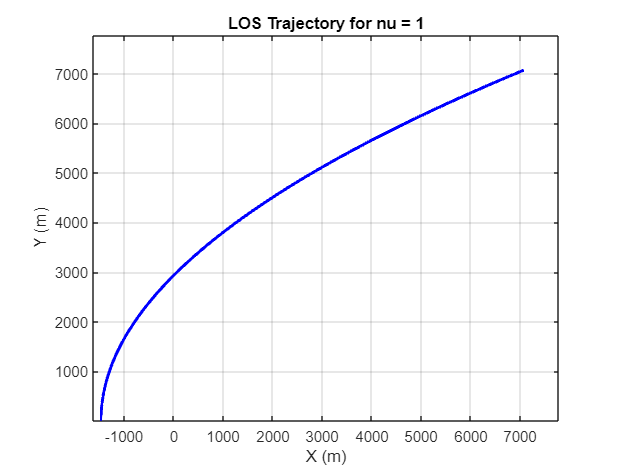

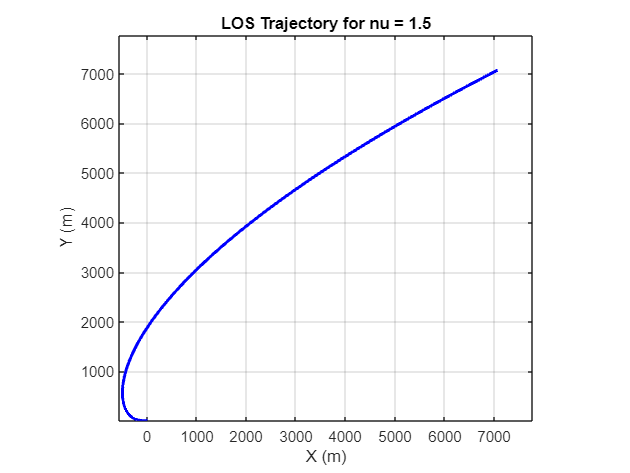

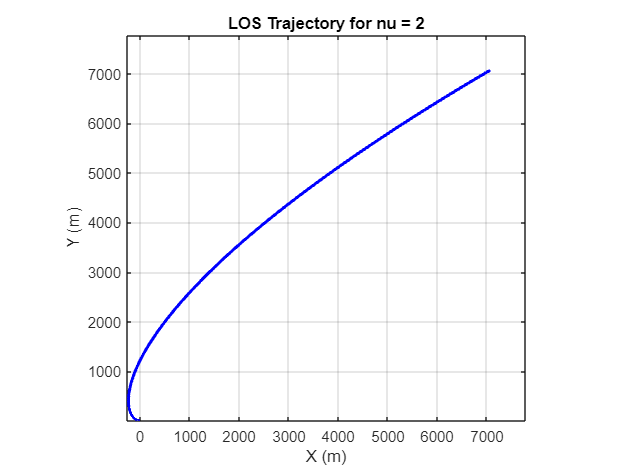

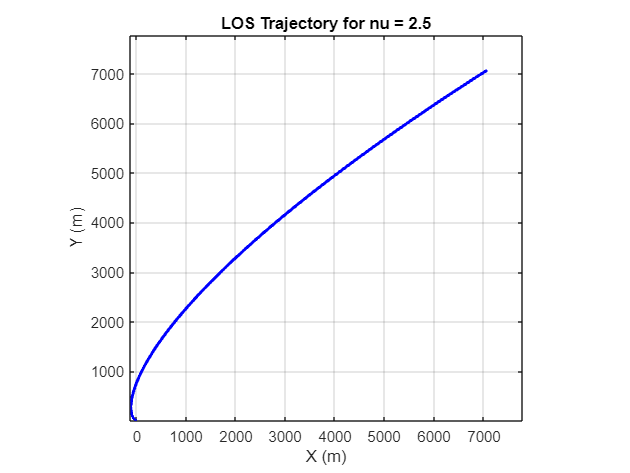

for i = 1:length(nu_values)
    R = R_results{i};
    theta = theta_results{i};
    [x, y] = pol2cart(theta, R);
    
    figure;
    %subplot(1, 2, 1);
    plot(x, y, 'b', 'LineWidth', 2);
    title(['LOS Trajectory for nu = ', num2str(nu_values(i))]);
    xlabel('X (m)');
    ylabel('Y (m)');
    axis equal;
    grid on;
    axis([(min(x))+0.1*(min(x)) (max(x))+0.1*(max(x)), (min(y))+0.1*(min(y)) (max(y))+0.1*(max(y))]);
    ytickformat('%g');
    
end

fprintf('Q2 Simulation R_miss values:\n');

Q2 Simulation R_miss values:


% R_miss for each nu
for i = 1:length(nu_values)
    nu = nu_values(i);
    % K = R0 * (sin(alphaT0 - theta0) / tan((alphaT0 - theta0) / 2))^nu;
    % R_miss = K * (tan((cos(nu))/2)^nu/(sin(acos(nu))));
    %R_results{i} = y(:,1);
    R_miss = min(R_results{i});
    disp(['Miss distance for nu = ', num2str(nu), ' is: ', num2str(R_miss), ' meters']);
end

Miss distance for nu = 0.5 is: 3992.9032 meters
Miss distance for nu = 1 is: 1464.4661 meters
Miss distance for nu = 1.5 is: 0.1 meters
Miss distance for nu = 2 is: 0.1 meters
Miss distance for nu = 2.5 is: 0.1 meters


% % am for init
% for i = 1:length(nu_values)
%     nu = nu_values(i);
%     K = R0 * (sin(alphaT0 - theta0) / tan((alphaT0 - theta0) / 2))^nu;
%     R_miss = K * (tan((cos(nu))/2)^nu/(sin(acos(nu))));

%     disp(['Miss distance for nu = ', num2str(nu), ' is: ', num2str(R_miss), ' meters']);
% end

function dy = pure_pursuit_odes(~, y, VT, nu, alphaT)
    R = y(1);
    theta = y(2);
    VM = nu * VT;

    VR = VT * cos(alphaT - theta) - VM;
    Vtheta = (VT / R) * sin(alphaT - theta);
    dRdt = VR;

    % K = 10000 * (sin(pi - deg2rad(45)) / tan((pi - deg2rad(45)) / 2))^nu;
    % aM = (VM * VT * sin(pi - deg2rad(45))^2) / (K * tan((pi - deg2rad(45))/2)^nu);

    dThetadt = Vtheta;
    % dy = [dRdt; dThetadt;aM];
    dy = [dRdt; dThetadt];
end

% Event
function [value,isterminal,direction] = projEvents(t,R)
    value = R(1) - 0.1; % Detect R - 0.1 m
    isterminal = 1; 
    direction = -1;
end
